b)

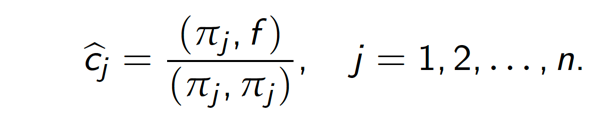

Aceasta este formula de calcul a coeficientilor unui polinom de aproximare in sensul celor mai mici patrate

Vom inlocui formula polinoamelor cu cea a polinoamelor ortogonale Chebysev#1 pentru a ajunge la formula din cerinta


$$c_j = \frac{(\pi_j, f)}{(\pi_j,\pi_k)} = \frac{(T_j(x_k), f(x_k))}{(T_j(x_k),T_j(x_k))} = \frac{1}{(T_j(x_k),T_j(x_k))}\sum_{k=0}^nf(x_k)*T_j(x_k)$$


Dar conform subpunctului a)


$$(T_j(x_k),T_j(x_k)) = \frac{n+1}{2}, j!=0$$


Deci formula noastra devine


$$c_j = \frac{2}{n+1}\sum_{k=0}^nf(x_k)*T_j(x_k)$$


e) Vom folosi formula de la subpunctul b si d pentru a ne crea formula de cuadratura

syms x;
n=5

n = 5

f = exp(x)*sin(x^2)

$$f = \sin\left(x^{2}\right)\,{\mathrm{e}}^{x}$$


GaussQuadCheb(f, 10)

ans = 2.3319e+14

double(int(f,x,-1,1))

ans = 0.8136

ab

function quad=GaussQuadCheb(f, n)
quad = 0;
exponents = calcExponent(f, n);
for i=0:2:n+1
    quad = quad + 2 * exponents(i+1)/(1-i^2);
end
end
function rez=calcExponent(f, n)

syms x;

rez = zeros(n,1);
for j=1:n+1
    sum = 0;
    for i=1:n+1
        sum = sum + subs(f,x,i - 1)*chebyshevT(j - 1, i - 1);
    end
    rez(j) = 2/(n+1)*sum;
end
end

